
syms x
syms y

M=@(x,y) [x y 15-(x+y);(20-2*x-y) 5 (2*x+y-10);(x+y-5) 10-y 10-x]

M = function_handle with value:
    @(x,y)[x,y,15-(x+y);(20-2*x-y),5,(2*x+y-10);(x+y-5),10-y,10-x]



M=M(4,9)

M =      4     9     2
     3     5     7
     8     1     6


v = M(:, 1);
M(:, 1) = M(:, 3);
M(:,3) = v;
M

M =      2     9     4
     7     5     3
     6     1     8



M3=magic(3)

M3 =      8     1     6
     3     5     7
     4     9     2


r=ones(3,1)

r =      1
     1
     1


S=transpose(r)*M3*r

S = 45


A = sym(pascal(4))

$$A = \left(\begin{array}{cccc} 1 & 1 & 1 & 1\\ 1 & 2 & 3 & 4\\ 1 & 3 & 6 & 10\\ 1 & 4 & 10 & 20 \end{array}\right)$$

dA = det(A)

$$dA = 1$$

A_adj = adjoint(A)

$$A\_adj = \left(\begin{array}{cccc} 4 & -6 & 4 & -1\\ -6 & 14 & -11 & 3\\ 4 & -11 & 10 & -3\\ -1 & 3 & -3 & 1 \end{array}\right)$$

A_inv = adjoint(A) / det(A)

$$A\_inv = \left(\begin{array}{cccc} 4 & -6 & 4 & -1\\ -6 & 14 & -11 & 3\\ 4 & -11 & 10 & -3\\ -1 & 3 & -3 & 1 \end{array}\right)$$



A = mod(pascal(4), 2)

A =      1     1     1     1
     1     0     1     0
     1     1     0     0
     1     0     0     0


A = sym(A)

$$A = \left(\begin{array}{cccc} 1 & 1 & 1 & 1\\ 1 & 0 & 1 & 0\\ 1 & 1 & 0 & 0\\ 1 & 0 & 0 & 0 \end{array}\right)$$

dA = det(A)

$$dA = 1$$

A_adj = adjoint(A)

$$A\_adj = \left(\begin{array}{cccc} 0 & 0 & 0 & 1\\ 0 & 0 & 1 & -1\\ 0 & 1 & 0 & -1\\ 1 & -1 & -1 & 1 \end{array}\right)$$

A_inv = adjoint(A) / det(A)

$$A\_inv = \left(\begin{array}{cccc} 0 & 0 & 0 & 1\\ 0 & 0 & 1 & -1\\ 0 & 1 & 0 & -1\\ 1 & -1 & -1 & 1 \end{array}\right)$$




A = sym(vander(1:4))

$$A = \left(\begin{array}{cccc} 1 & 1 & 1 & 1\\ 8 & 4 & 2 & 1\\ 27 & 9 & 3 & 1\\ 64 & 16 & 4 & 1 \end{array}\right)$$

dA = det(A)

$$dA = 12$$

A_adj = adjoint(A)

$$A\_adj = \left(\begin{array}{cccc} -2 & 6 & -6 & 2\\ 18 & -48 & 42 & -12\\ -52 & 114 & -84 & 22\\ 48 & -72 & 48 & -12 \end{array}\right)$$

A_inv = adjoint(A) / det(A)

$$A\_inv = \left(\begin{array}{cccc} -\frac{1}{6} & \frac{1}{2} & -\frac{1}{2} & \frac{1}{6}\\ \frac{3}{2} & -4 & \frac{7}{2} & -1\\ -\frac{13}{3} & \frac{19}{2} & -7 & \frac{11}{6}\\ 4 & -6 & 4 & -1 \end{array}\right)$$


Z=[1 2 3; 4 5 6; 7 8 9]

Z =      1     2     3
     4     5     6
     7     8     9


A=sym(Z)

$$A = \left(\begin{array}{ccc} 1 & 2 & 3\\ 4 & 5 & 6\\ 7 & 8 & 9 \end{array}\right)$$

dA = det(A)

$$dA = 0$$

A_adj = adjoint(A)

$$A\_adj = \left(\begin{array}{ccc} -3 & 6 & -3\\ 6 & -12 & 6\\ -3 & 6 & -3 \end{array}\right)$$




A = eye(1000); whos A

  Name         Size                Bytes  Class     Attributes

  A         1000x1000            8000000  double              



S = sparse(A); whos S

  Name         Size              Bytes  Class     Attributes

  S         1000x1000            24008  double    sparse    



S = sparse(50,50)

S =    All zero sparse: 50×50


S = sparse(3,4);
A = full(S)

A =      0     0     0     0
     0     0     0     0
     0     0     0     0


I10 = sparse(eye(10))

I10 =    (1,1)        1
   (2,2)        1
   (3,3)        1
   (4,4)        1
   (5,5)        1
   (6,6)        1
   (7,7)        1
   (8,8)        1
   (9,9)        1
  (10,10)       1


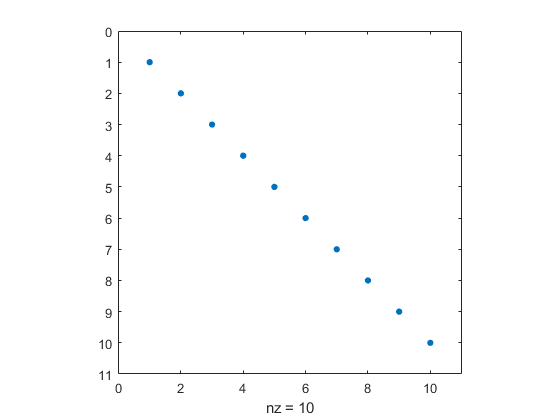

spy(I10)

i = [1:10, 1:10];
j = [1:10, 10:-1:1];
k = ones(size(i));
A = sparse(i, j, k)

A =    (1,1)        1
  (10,1)        1
   (2,2)        1
   (9,2)        1
   (3,3)        1
   (8,3)        1
   (4,4)        1
   (7,4)        1
   (5,5)        1
   (6,5)        1
   (5,6)        1
   (6,6)        1
   (4,7)        1
   (7,7)        1
   (3,8)        1
   (8,8)        1
   (2,9)        1
   (9,9)        1
   (1,10)       1
  (10,10)       1


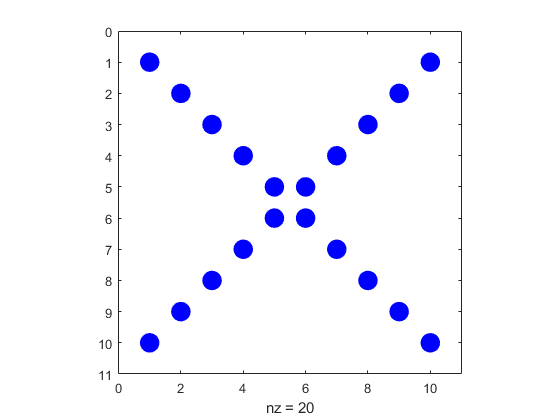

spy(A, 'blue', 50)

A = sparse([5, 6], [5, 6], [3, -3],10,10) 

A =    (5,5)        3
   (6,6)       -3


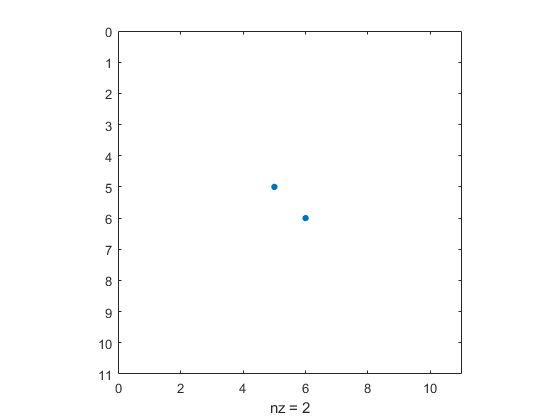

spy(A)

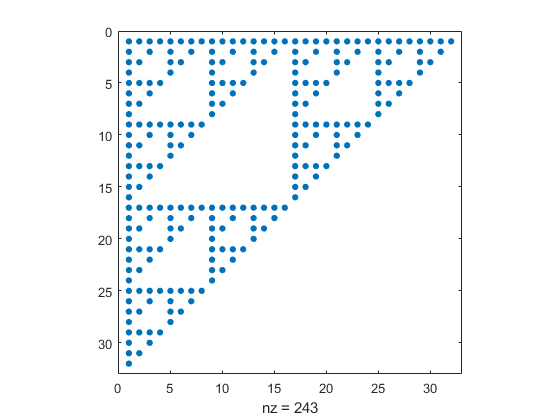



P = pascal(32);
s = rem(P,2);
spy(s)



A = mod(pascal(4),2)

A =      1     1     1     1
     1     0     1     0
     1     1     0     0
     1     0     0     0


I = eye(4)

I =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


AI = [A , I]

AI =      1     1     1     1     1     0     0     0
     1     0     1     0     0     1     0     0
     1     1     0     0     0     0     1     0
     1     0     0     0     0     0     0     1


RREF = rref(AI)

RREF =      1     0     0     0     0     0     0     1
     0     1     0     0     0     0     1    -1
     0     0     1     0     0     1     0    -1
     0     0     0     1     1    -1    -1     1


inverse_AI = RREF(:,[5 6 7 8])

inverse_AI =      0     0     0     1
     0     0     1    -1
     0     1     0    -1
     1    -1    -1     1




n = 5

n = 5

X = -ones(n-1,1)

X =     -1
    -1
    -1
    -1


Y = 2*ones(n,1)

Y =      2
     2
     2
     2
     2


Z = X

Z =     -1
    -1
    -1
    -1


A = gallery('tridiag', X, Y, Z)

A =    (1,1)        2
   (2,1)       -1
   (1,2)       -1
   (2,2)        2
   (3,2)       -1
   (2,3)       -1
   (3,3)        2
   (4,3)       -1
   (3,4)       -1
   (4,4)        2
   (5,4)       -1
   (4,5)       -1
   (5,5)        2


A = sym(full(A))

$$A = \left(\begin{array}{ccccc} 2 & -1 & 0 & 0 & 0\\ -1 & 2 & -1 & 0 & 0\\ 0 & -1 & 2 & -1 & 0\\ 0 & 0 & -1 & 2 & -1\\ 0 & 0 & 0 & -1 & 2 \end{array}\right)$$

detA = det(A)

$$detA = 6$$

inverseA = inv(A)

$$inverseA = \left(\begin{array}{ccccc} \frac{5}{6} & \frac{2}{3} & \frac{1}{2} & \frac{1}{3} & \frac{1}{6}\\ \frac{2}{3} & \frac{4}{3} & 1 & \frac{2}{3} & \frac{1}{3}\\ \frac{1}{2} & 1 & \frac{3}{2} & 1 & \frac{1}{2}\\ \frac{1}{3} & \frac{2}{3} & 1 & \frac{4}{3} & \frac{2}{3}\\ \frac{1}{6} & \frac{1}{3} & \frac{1}{2} & \frac{2}{3} & \frac{5}{6} \end{array}\right)$$

adjA  = adjoint(A)

$$adjA = \left(\begin{array}{ccccc} 5 & 4 & 3 & 2 & 1\\ 4 & 8 & 6 & 4 & 2\\ 3 & 6 & 9 & 6 & 3\\ 2 & 4 & 6 & 8 & 4\\ 1 & 2 & 3 & 4 & 5 \end{array}\right)$$

verify = 1/6*adjA

$$verify = \left(\begin{array}{ccccc} \frac{5}{6} & \frac{2}{3} & \frac{1}{2} & \frac{1}{3} & \frac{1}{6}\\ \frac{2}{3} & \frac{4}{3} & 1 & \frac{2}{3} & \frac{1}{3}\\ \frac{1}{2} & 1 & \frac{3}{2} & 1 & \frac{1}{2}\\ \frac{1}{3} & \frac{2}{3} & 1 & \frac{4}{3} & \frac{2}{3}\\ \frac{1}{6} & \frac{1}{3} & \frac{1}{2} & \frac{2}{3} & \frac{5}{6} \end{array}\right)$$



I = eye(5)

I =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


AI = [A I]

$$AI = \left(\begin{array}{cccccccccc} 2 & -1 & 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ -1 & 2 & -1 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & -1 & 2 & -1 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & -1 & 2 & -1 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & -1 & 2 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

REF = rref(AI)

$$REF = \left(\begin{array}{cccccccccc} 1 & 0 & 0 & 0 & 0 & \frac{5}{6} & \frac{2}{3} & \frac{1}{2} & \frac{1}{3} & \frac{1}{6}\\ 0 & 1 & 0 & 0 & 0 & \frac{2}{3} & \frac{4}{3} & 1 & \frac{2}{3} & \frac{1}{3}\\ 0 & 0 & 1 & 0 & 0 & \frac{1}{2} & 1 & \frac{3}{2} & 1 & \frac{1}{2}\\ 0 & 0 & 0 & 1 & 0 & \frac{1}{3} & \frac{2}{3} & 1 & \frac{4}{3} & \frac{2}{3}\\ 0 & 0 & 0 & 0 & 1 & \frac{1}{6} & \frac{1}{3} & \frac{1}{2} & \frac{2}{3} & \frac{5}{6} \end{array}\right)$$

inverse_AI = REF(:,[6 7 8 9 10])

$$inverse\_AI = \left(\begin{array}{ccccc} \frac{5}{6} & \frac{2}{3} & \frac{1}{2} & \frac{1}{3} & \frac{1}{6}\\ \frac{2}{3} & \frac{4}{3} & 1 & \frac{2}{3} & \frac{1}{3}\\ \frac{1}{2} & 1 & \frac{3}{2} & 1 & \frac{1}{2}\\ \frac{1}{3} & \frac{2}{3} & 1 & \frac{4}{3} & \frac{2}{3}\\ \frac{1}{6} & \frac{1}{3} & \frac{1}{2} & \frac{2}{3} & \frac{5}{6} \end{array}\right)$$

b = [0;0;0;0;6]

b =      0
     0
     0
     0
     6


IB = inverse_AI*b

$$IB = \left(\begin{array}{c} 1\\ 2\\ 3\\ 4\\ 5 \end{array}\right)$$

check = A*IB-b

$$check = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$



clear, clc
A11 = pascal(3)

A11 =      1     1     1
     1     2     3
     1     3     6


A12 = pascal(3); A12 = A12(:, 1:2)

A12 =      1     1
     1     2
     1     3


A21 = zeros(2,3)

A21 =      0     0     0
     0     0     0


A22 = pascal(2)

A22 =      1     1
     1     2


A = [A11 A12; A21 A22]

A =      1     1     1     1     1
     1     2     3     1     2
     1     3     6     1     3
     0     0     0     1     1
     0     0     0     1     2


inverse = inv(A)

inverse =      3    -3     1    -2     1
    -3     5    -2     1    -1
     1    -2     1     0     0
     0     0     0     2    -1
     0     0     0    -1     1


x = inv(A11)

x =     3.0000   -3.0000    1.0000
   -3.0000    5.0000   -2.0000
    1.0000   -2.0000    1.0000


y = inv(A22)

y =      2    -1
    -1     1


C = -x * A12 * y

C =    -2.0000    1.0000
    1.0000   -1.0000
         0         0


A_inv = [x C;A21 y]

A_inv =     3.0000   -3.0000    1.0000   -2.0000    1.0000
   -3.0000    5.0000   -2.0000    1.0000   -1.0000
    1.0000   -2.0000    1.0000         0         0
         0         0         0    2.0000   -1.0000
         0         0         0   -1.0000    1.0000





message = 'Beware the Jabberwock, my son!The jaws that bite, the claws that catch!Beware the Jubjub bird,and shun The frumious Bandersnatch!'

message = 'Beware the Jabberwock, my son!The jaws that bite, the claws that catch!Beware the Jubjub bird,and shun The frumious Bandersnatch!'

while mod(length(message),3) ~= 0
message = [message ' '] 
end

M = reshape( message, 3, []) 

M = 3×43 char array
    'Ba eaeo,yoT wtti,hcwttahert bbi,dh erisaenc'
    'ert brc  nhjsh t elsh t!wehJj ra uT uo nrah'
    'wehJbwkms!ea abet a accBa euubdnsnhfmuBdst!'


A = [1 -2 2; 2 -1 2; 2 -2 3] 

A =      1    -2     2
     2    -1     2
     2    -2     3


coded_message = A*M

coded_message =    102    71     8   185    97   111   127   198   287   -43    78    14   -47   102   248    75   212   -34    77   -47   102   250    63   170    57   -24   110   118   120   230    77    70   266    90    72   241    98   117   183    77   103   148   -43
   269   282   156   318   292   326   337   274   440   178   266   152   187   322   396   296   288   171   284   187   322   398   276   307   277   191   330   224   324   360   296   211   398   311   188   374   329   333   330   284   318   355   160
   287   269   144   360   292   331   345   351   523   101   263   143   104   315   462   281   372   102   273   104   315   465   259   340   255   122   327   267   335   426   282   224   481   304   208   444   321   339   364   274   319   374    89


decoder = round( inv(A) )

decoder =      1     2    -2
    -2    -1     2
    -2    -2     3


message_in_a_matrix = decoder*coded_message

message_in_a_matrix =     66    97    32   101    97   101   111    44   121   111    84    32   119   116   116   105    44   104    99   119   116   116    97   104   101   114   116    32    98    98   105    44   100   104    32   101   114   105   115    97   101   110    99
   101   114   116    32    98   114    99    32    32   110   104   106   115   104    32   116    32   101   108   115   104    32   116    33   119   101   104    74   106    32   114    97    32   117    84    32   117   111    32   110   114    97   104
   119   101   104    74    98   119   107   109   115    33   101    97    32    97    98   101   116    32    97    32    97    99    99    66    97    32   101   117   117    98   100   110   115   110   104   102   109   117    66   100   115   116    33


original_message = char( reshape( message_in_a_matrix, 1, [] ) )

original_message = 'Beware the Jabberwock, my son!The jaws that bite, the claws that catch!Beware the Jubjub bird,and shun The frumious Bandersnatch!'

fprintf(original_message)

Beware the Jabberwock, my son!The jaws that bite, the claws that catch!Beware the Jubjub bird,and shun The frumious Bandersnatch!



coded_message1 = [68 258 278 -34 88 -59 95 121 111 -49 -61 257 109 77 -20 110 240 -53 249 115 121 18 71 86 8 -71 129 -65 133 5 4 -51 110 6 -55 107 144 -23 -61 119 85 30 267 138 38 119 252 115 71 121 140 187 69 105 116 99 -64;237 402 420 171 309 148 322 342 315 183 159 386 324 289 199 321 372 172 378 329 317 167 294 315 156 142 335 151 349 221 206 182 330 152 150 334 363 193 159 324 303 173 400 355 168 351 384 329 216 198 351 326 284 320 192 326 138;237 475 504 102 301 70 311 347 321 100 76 466 328 279 130 321 442 90 454 331 328 160 277 301 144 58 345 68 358 166 162 98 327 139 74 329 376 124 76 335 297 172 483 366 171 350 460 331 202 236 364 366 268 322 228 317 60]

coded_message1 =     68   258   278   -34    88   -59    95   121   111   -49   -61   257   109    77   -20   110   240   -53   249   115   121    18    71    86     8   -71   129   -65   133     5     4   -51   110     6   -55   107   144   -23   -61   119    85    30   267   138    38   119   252   115    71   121
   237   402   420   171   309   148   322   342   315   183   159   386   324   289   199   321   372   172   378   329   317   167   294   315   156   142   335   151   349   221   206   182   330   152   150   334   363   193   159   324   303   173   400   355   168   351   384   329   216   198
   237   475   504   102   301    70   311   347   321   100    76   466   328   279   130   321   442    90   454   331   328   160   277   301   144    58   345    68   358   166   162    98   327   139    74   329   376   124    76   335   297   172   483   366   171   350   460   331   202   236


decode = round(inv(A))

decode =      1     2    -2
    -2    -1     2
    -2    -2     3


message1 = decode*coded_message1

message1 =     68   112   110   104   104    97   117   111    99   117   105    97   101    97   118   110   100   111    97   111    99    32   105   114    32    97   109   101   115   115    92   117   116    32    97   117   118   115   105    97    97    32   101   116    32   121   100   111    99    45
   101    32    32   101   117   110   110   110   105   115   115    32   114   115   101   101    32   114    32   103    97   117   118   115   116   116    97   115   101   101   110   116   104   114   108   110   101   101   115   108   121   111    32   101    98   111    32   103    46    32
   101   105   116    32   109    32    99   115   111    32    32   112   118   105    32   101   102    32   108   105   108   110   101   101   104    32   107    32   110    46    66    32   101   101    32   105   114    32    32   119   115   110   115   112   101   110   108   105    32    70


original = char(reshape(message1,1,[]))

original = 'Deep in the human unconscious is a pervasive need for a logical universe that makes sense.\nBut the real universe is always one step beyond logic. - Frank Herbert, Dune\n '

fprintf(original)

Deep in the human unconscious is a pervasive need for a logical universe that makes sense.
But the real universe is always one step beyond logic. - Frank Herbert, Dune
 